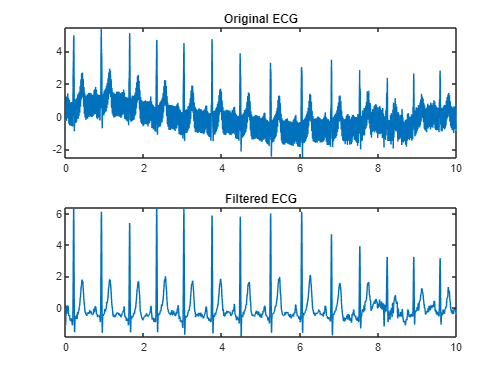

fs = 500;  %sampling frequency
T = 1/fs;  %sampling period
t = (0:1/fs:10-1/fs);


x = readmatrix('C:\Users\Kimberly Alvaro\Desktop\LBYEC4A Proj\ECG Database\original_ecg.csv');
x = normalize(x);
n = length(x);

X = readmatrix('C:\Users\Kimberly Alvaro\Desktop\LBYEC4A Proj\ECG Database\filtered_ecg.xlsx');
X = normalize(X);
N = length(X);

f = (0:n-1)*(fs/n); %freq range

figure(1)
subplot(211); plot(t,x); title("Original ECG");
subplot(212); plot(t,X); title("Filtered ECG");